# boas praticas

clear all
close all
clc

## leitura dados

T = readtable('SIRpd.csv');   % lendo dados csv e transformando em tabela
T = table2array(T)            % transformando tabela em array

T =   499.0000    1.0000         0
  498.9490    1.0407    0.0102
  498.8960    1.0831    0.0208
  498.8408    1.1273    0.0319
  498.7834    1.1732    0.0434
  498.7236    1.2210    0.0554
  498.6615    1.2707    0.0679
  498.5968    1.3224    0.0808
  498.5294    1.3762    0.0943
  498.4594    1.4322    0.1084


%% Indexando cada parte da tabela para separar S R e I
Sd = T(:,1)                   

Sd =   499.0000
  498.9490
  498.8960
  498.8408
  498.7834
  498.7236
  498.6615
  498.5968
  498.5294
  498.4594


Id = T(:,2)

Id =     1.0000
    1.0407
    1.0831
    1.1273
    1.1732
    1.2210
    1.2707
    1.3224
    1.3762
    1.4322


Rd = T(:,3)

Rd =          0
    0.0102
    0.0208
    0.0319
    0.0434
    0.0554
    0.0679
    0.0808
    0.0943
    0.1084


## gerando numeros aleatórios para somar com os dados do csv


Sdn = rand(1000, 1) 

Sdn =     0.0522
    0.1650
    0.2534
    0.7102
    0.7576
    0.8598
    0.8070
    0.3585
    0.6691
    0.4074


Idn = rand(1000, 1)

Idn =     0.1266
    0.7539
    0.9566
    0.6346
    0.7896
    0.1063
    0.9929
    0.0504
    0.0220
    0.8546


Rdn = rand(1000, 1) 

Rdn =     0.0476
    0.1971
    0.7702
    0.1127
    0.1775
    0.9144
    0.9044
    0.0463
    0.0238
    0.8089


## somando números aleatórios com os dados do csv para gerar erro gaussiano


Sd = Sd + Sdn

Sd =   499.0522
  499.1141
  499.1494
  499.5511
  499.5410
  499.5834
  499.4685
  498.9553
  499.1986
  498.8667


Id = Id + Idn

Id =     1.1266
    1.7946
    2.0398
    1.7619
    1.9627
    1.3272
    2.2636
    1.3728
    1.3982
    2.2868


Rd = Rd + Rdn

Rd =     0.0476
    0.2073
    0.7911
    0.1446
    0.2210
    0.9698
    0.9722
    0.1271
    0.1182
    0.9173


## Visualizando a evolução da Epidemia - S(t), I(t) e R(t)


t = linspace(0,length(Sd),length(Sd))

t = 	1.0e+03 *

         0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


figure(1)
subplot(3,1,1)
plot(t,Sd, marker='o', color='b')
legend('Suscetíveis - dados')
subplot(3,1,2)

plot(t,Id, marker='*', color='k')
legend('Infectados - dados')
subplot(3,1,3)
plot(t,Rd, marker='+', color='c')
legend('Removidos - dados')

xlabel = ('Dias')

xlabel = 'Dias'

ylabel = ('Indivíduos')

ylabel = 'Indivíduos'


ylim = [0,600]

ylim =      0   600


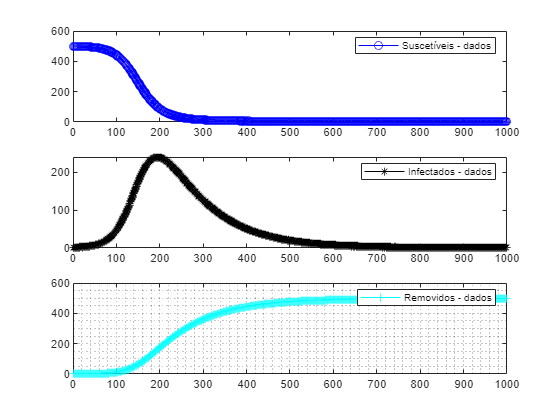

grid minor

## Chamando modelo SIR

% Tamanho da populção - N
N = 500

N = 500


% Valores iniciais 
i0 = 1 

i0 = 1

r0 = 0

r0 = 0

s0 = N - i0

s0 = 499


% Vetor de condições iniciais

y0 = [s0 i0 r0]

y0 =    499     1     0



% Beta -  taxa de contato,
% r - taxa média de recuperação (in 1/dia).

theta0 = [1e-4,1e-2] % valores iniciais

theta0 =     0.0001    0.0100


beta = theta0(1)

beta = 1.0000e-04

r = theta0(2)

r = 0.0100

% Definição do conjunto de equações diferencias não lineares que formam o modelo.

t = linspace(0,1000,1000)

t = 	1.0e+03 *

         0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490



 
mdl = 'SimulacaoSIR';
load_system(mdl)
cs = getActiveConfigSet(mdl);
mdl_cs = cs.copy;
set_param(mdl_cs,'AbsTol','1e-5',...
         'SaveState','on','StateSaveName','xoutNew',...
         'SaveOutput','on','OutputSaveName','youtNew')
simOut = sim(mdl, mdl_cs)

simOut =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [54x1 double] 
                xoutNew: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## visualizando dados modelo

S = simOut.logsout{1}.Values.Data

S =   499.0000
  498.9899
  498.9384
  498.6472
  497.1694
  493.4480
  485.3825
  468.4462
  435.1236
  377.1695


I = simOut.logsout{2}.Values.Data

I =     1.0000
    1.0081
    1.0493
    1.2820
    2.4631
    5.4332
   11.8507
   25.2354
   51.1792
   94.8402


R = simOut.logsout{3}.Values.Data

R =          0
    0.0020
    0.0124
    0.0707
    0.3675
    1.1189
    2.7669
    6.3184
   13.6973
   27.9903



t = linspace(0,length(S),length(S))

t =          0    1.0189    2.0377    3.0566    4.0755    5.0943    6.1132    7.1321    8.1509    9.1698   10.1887   11.2075   12.2264   13.2453   14.2642   15.2830   16.3019   17.3208   18.3396   19.3585   20.3774   21.3962   22.4151   23.4340   24.4528   25.4717   26.4906   27.5094   28.5283   29.5472   30.5660   31.5849   32.6038   33.6226   34.6415   35.6604   36.6792   37.6981   38.7170   39.7358   40.7547   41.7736   42.7925   43.8113   44.8302   45.8491   46.8679   47.8868   48.9057   49.9245



figure(2)

subplot(3,1,1)
scatter(t, S, marker='o', color='b')
legend('Suscetíveis')

subplot(3,1,2)
scatter(t, I, marker='*', color='k')
legend('Infectados')

subplot(3,1,3)
scatter(t, R, marker='+', color='c')
legend('Removidos')

xlabel = ('Dias')

xlabel = 'Dias'

ylabel = ('Indivíduos')

ylabel = 'Indivíduos'

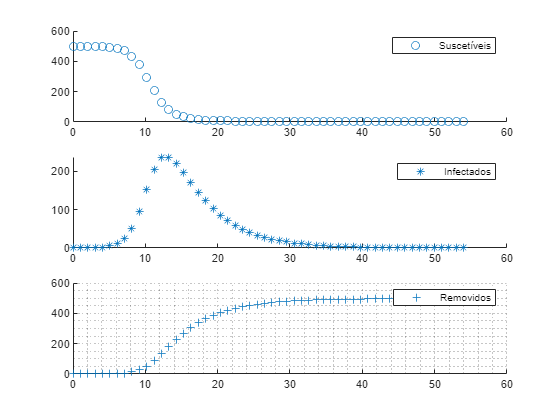


grid minor